# Optima Bodluv

option = "Trias";

## Level Effektoren Blau

"Welcher blaue Effektor hat gegen welche Bedrohung (rote Systeme) wie performt?"

sheetName = "red_air_killed_by_effector";
data = importData(sheetName, option);
data.BlueEffector = replace(string(data.BlueEffector), "_", "-");
data.RedSystem = replace(string(data.RedSystem), "_", "-");
dataVar = "InDeployedREDAIR";

#### Performanz pro Effektor blau

grpVar = "BlueEffector";
univarStats(data, grpVar, dataVar);

#### Performanz pro Effektor blau und System rot

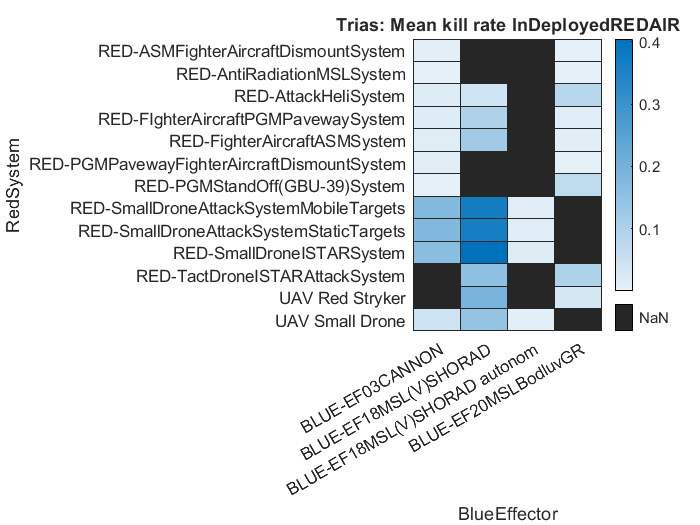

grpVar = ["BlueEffector"; "RedSystem"];
statarray = grpstats(data, grpVar, "mean", "DataVars", dataVar);
figure("Name", "PerformanceEffektorBlau"+option)
heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none")
title(option+": Mean kill rate "+dataVar)

## Level Systeme Blau

"Welches blaue System hat gegen welche Bedrohung (rote Systeme) wie performt?"

sheetName = "red_air_killed_by_system";
data = importData(sheetName, option);
data.BlueSystem = replace(string(data.BlueSystem), "_", "-");
data.RedSystem = replace(string(data.RedSystem), "_", "-");

#### Performanz pro System blau

grpVar = "BlueSystem";
univarStats(data, grpVar, dataVar);

#### Performanz pro System blau (Angreifer) und System rot

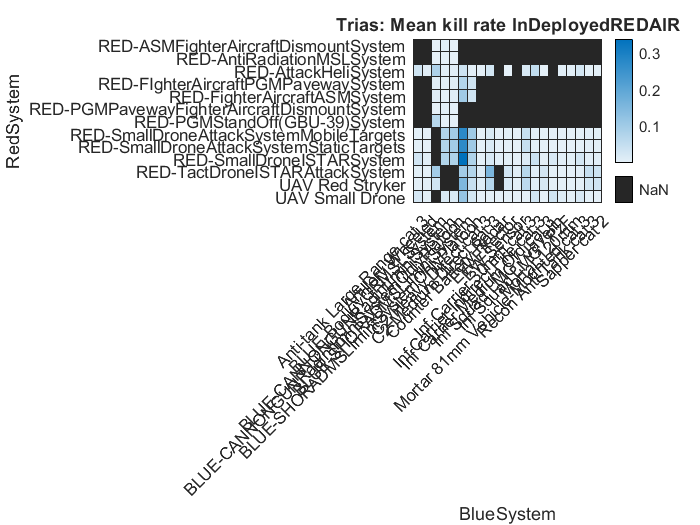

grpVar = ["BlueSystem"; "RedSystem"];
statarray = grpstats(data, grpVar, "mean", "DataVars", dataVar);
figure("Name", "PerformanceSystemBlau"+option)
h = heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none");
title(option+": Mean kill rate "+dataVar)

## Level Systeme Rot

"Welches rote System hat gegen welches blaue System wie performt?"

sheetName = "blue_killed_by_red_system";
data = importData(sheetName, option);
data.BlueSystem = replace(string(data.BlueSystem), "_", "-");
data.RedSystem = replace(string(data.RedSystem), "_", "-");
dataVar = "InDeployedBLUE";

#### Performanz pro System rot

grpVar = "RedSystem";
univarStats(data, grpVar, dataVar);

#### Performanz pro System rot (Angreifer) und System blau

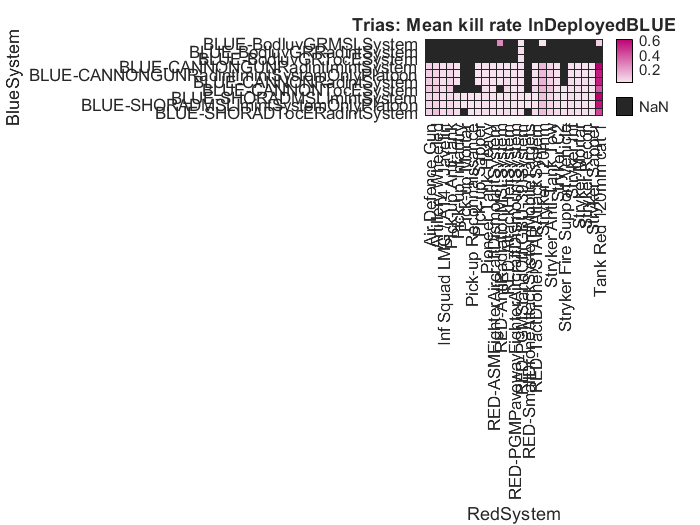

grpVar = ["RedSystem"; "BlueSystem"];
statarray = grpstats(data, grpVar, "mean", "DataVars", dataVar);
figure("Name", "PerformanceSystemRot"+option)
heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none", 'Colormap', h.Colormap(:, [3, 1, 2]))
title(option+": Mean kill rate "+dataVar)

#### Anzahl verlorene Bodluv-Systeme

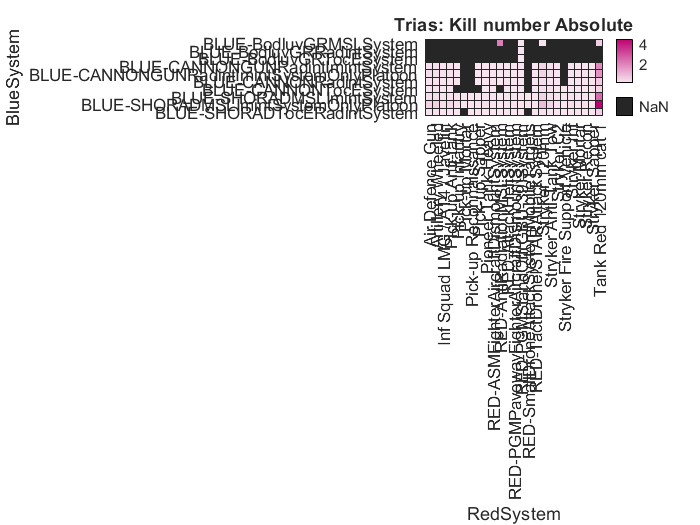

dataVar = "Absolute";
statarray = grpstats(data, grpVar, "mean", "DataVars", dataVar);
figure("Name", "PerformanceSystemRotAbsolut"+option)
heatmap(statarray, grpVar{1}, grpVar{2}, 'ColorVariable', "mean_"+dataVar, "ColorMethod", "none", 'Colormap', h.Colormap(:, [3, 1, 2]))
title(option+": Kill number "+dataVar)